diffusion = importdata("data.xlsx")

diffusion = struct with fields:
          data: [1×1 struct]
      textdata: [1×1 struct]
    colheaders: [1×1 struct]


dif1 = diffusion.data.dif_1

dif1 =            0        1359
           5        1356
          10        1355
          15        1344
          20        1329
          25        1300
          30        1268
          35        1237
          40        1207
          45        1180


dif2 = diffusion.data.dif_2

dif2 =      0   914
     5   901
    10   899
    15   887
    20   874
    25   868
    30   848
    35   834
    40   819
    45   808


dif3 = diffusion.data.dif_3

dif3 =      0   782
     5   777
    10   773
    15   766
    20   757
    25   749
    30   740
    35   731
    40   723
    45   714


dif4 = diffusion.data.dif_4

dif4 =      0   748
     5   744
    10   741
    15   735
    20   730
    25   724
    30   718
    35   712
    40   706
    45   700


dif5 = diffusion.data.dif_5

dif5 =      0   628
     5   616
    10   616
    15   613
    20   607
    25   604
    30   598
    35   591
    40   585
    45   580


x_1 = transpose(dif1(: ,1))

x_1 =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180


y_1 = transpose(dif1(:, 2))

y_1 =         1359        1356        1355        1344        1329        1300        1268        1237        1207        1180        1158        1124        1098        1072        1045        1028         997         969         946         924         902         880         858         839         819         799         778         759         741         722         705         688         669         653         638         620         607


x_2 = transpose(dif2(: ,1))

x_2 =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210


y_2 = transpose(dif2(:, 2))

y_2 =    914   901   899   887   874   868   848   834   819   808   797   783   772   760   747   737   727   716   706   694   684   679   666   656   646   636   625   616   609   599   592   584   575   566   557   549   542   539   528   518   511   503   498


x_3 = transpose(dif3(: ,1))

x_3 =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210


y_3 = transpose(dif3(:, 2))

y_3 =    782   777   773   766   757   749   740   731   723   714   706   699   692   685   677   669   662   656   647   642   633   627   622   614   607   603   596   589   586   580   573   568   563   554   550   544   539   534   528   525   520   516   508


x_4 = transpose(dif4(: ,1))

x_4 =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210


y_4 = transpose(dif4(:, 2))

y_4 =    748   744   741   735   730   724   718   712   706   700   692   686   679   673   668   663   657   653   645   641   634   632   626   621   614   610   604   602   596   591   587   581   576   571   569   565   561   557   552   549   545   540   537


x_5 = transpose(dif5(: ,1))

x_5 =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175   180   185   190   195   200   205   210


y_5 = transpose(dif5(:, 2))

y_5 =    628   616   616   613   607   604   598   591   585   580   577   571   567   562   557   554   550   547   540   537   533   530   525   523   518   514   513   508   504   502   498   494   494   490   487   483   482   477   476   470   468   464   464


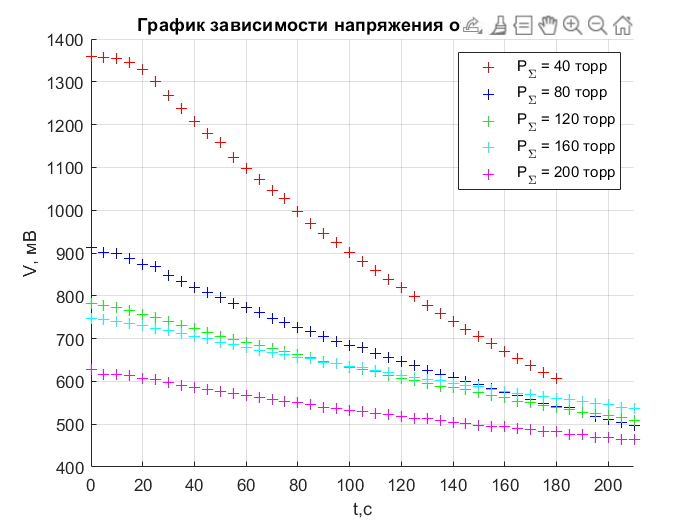

fg1 = figure;
hold on
grid on
xlim([0,210])
plot(x_1, y_1, '+r');
plot(x_2, y_2, '+b');
plot(x_3, y_3, '+g');
plot(x_4, y_4, '+c');
plot(x_5, y_5, '+m');

xlabel(['t,' 'c'])
ylabel("V, мВ")
legend("P_{\Sigma} = 40 торр", "P_{\Sigma} = 80 торр", "P_{\Sigma} = 120 торр", "P_{\Sigma} = 160 торр", "P_{\Sigma} = 200 торр")
title("График зависимости напряжения от времени V(t)")

set(fg1, "Visible", 'on')
hold off 